# Transform compound Exercise 2

Team: 

Javier Cabrera

Julia Gasull

Link: [https://drive.matlab.com/sharing/49eb5fa6-0641-425c-a130-9cf41b2e1058](https://drive.matlab.com/sharing/49eb5fa6-0641-425c-a130-9cf41b2e1058)

Path: /MATLAB Drive/JJ/Todo3_Sketching_a_Robotic_Cell/Transform_Operator/FromTheory2Practice

See the video: [https://youtu.be/KZnt6XtVTtY](https://youtu.be/KZnt6XtVTtY)

## Organize your ideas and make and skecth 

Think about: 

- Vision system give you the kind of box (Small / Big) and the pose wrt reference frame ot the Conveyor (cinta) belt, i.e. T_caja_Conveyor

- There are two Pallets for boxes (Small / Big)

- Is not a 3D ploblem --> ES EN 2D

- think in real dimensions

Specs:

- Small box -> 30x30cm

- Big box -> 40x40cm

- Distance between conveyer belt and small pack -> 20 cm

- Distance between packs -> 40 cm

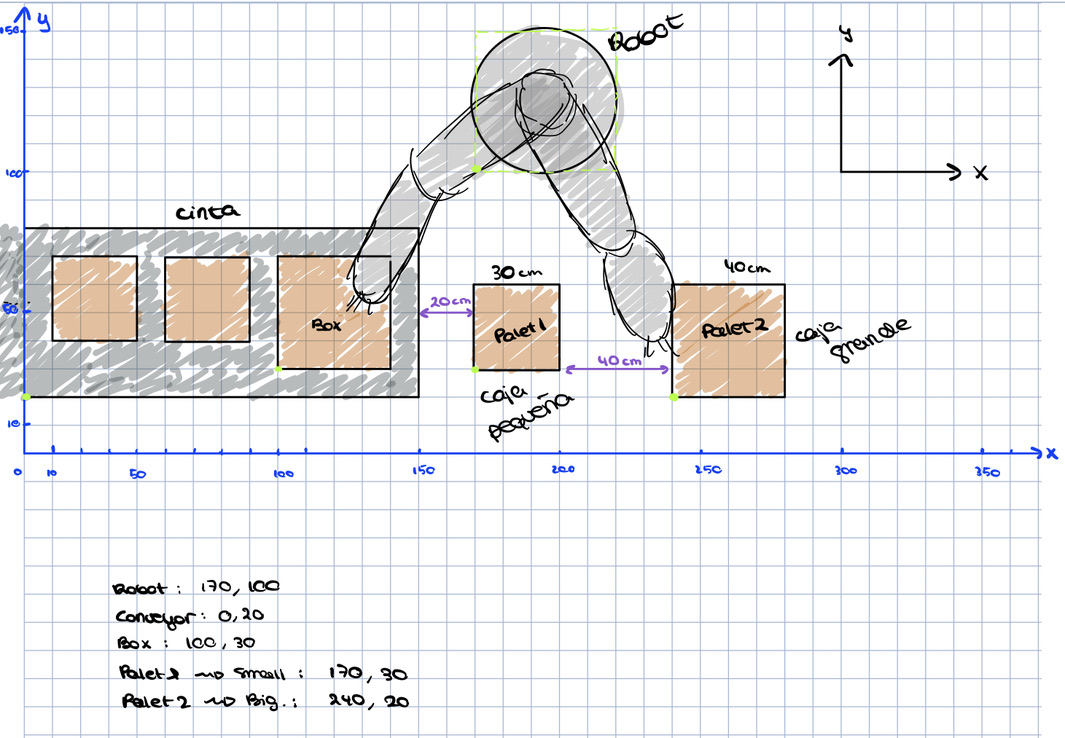

## Draw a Matlab Figure and find ${}^R{P_{Caja}$

Suponemos:

- La Box está inicialmente rotada -30º

- La Box está en la posición [100 30] respecto nuestro punto de origen

- Necesitamos trasladar la Box hasta el Palet2, que está en la posición [240 20] y después rotarla 30º para que esté alineada con éste

Por tanto, tenemos que encontrar:

- Matriz de translación desde el robot hasta box

- Matriz de translación desde el box hasta palet2

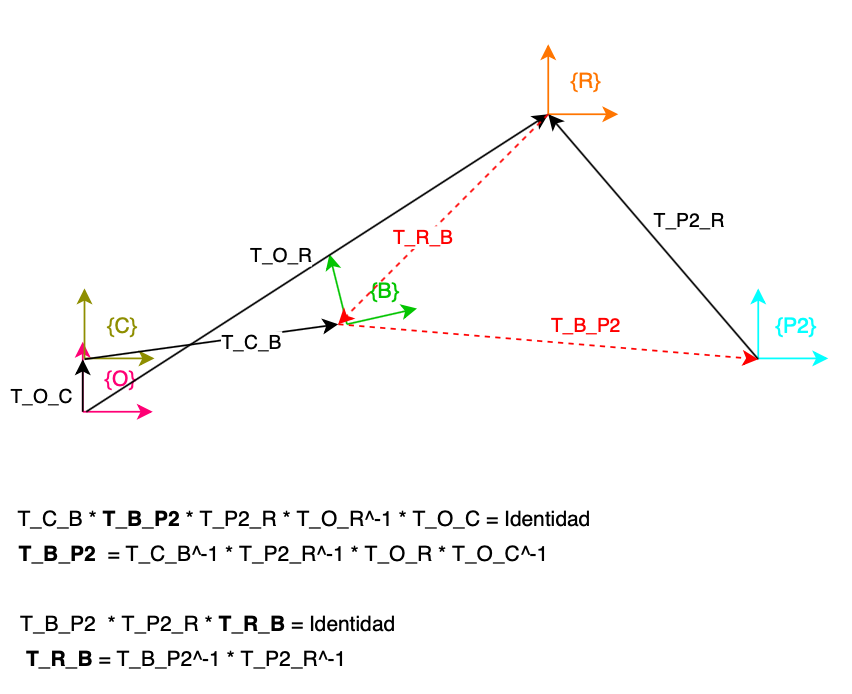

## Declaramos las translaciones

### Puntos de ejemplo

Inicialmente, definiremos todos nuestros objetos de referencia como ejemplo:

robot    = [170 100 0]'

robot =    170
   100
     0


conveyor = [  0  20 0]'

conveyor =      0
    20
     0


box      = [100  30 0]'

box =    100
    30
     0


pallet1  = [170  30 0]'

pallet1 =    170
    30
     0


pallet2  = [240  20 0]'

pallet2 =    240
    20
     0


### Translaciones base

Ahora, vamos a definir las translaciones que ya tenemos (ver imagen: flechas negras)

T_C_B  = transl2(100, 10) * trot2(-30, 'deg');
T_P2_R = transl2(-70, 80);
T_O_R  = transl2(170,100);
T_O_C  = transl2(  0, 20);

### Translaciones calculadas

Ahora vamos a encontrar T_R_B para llegar a coger la caja y T_B_P2 para dejar la caja en el Palet2:

% para mejor gestión de cálculo, empezamos por buscar T_B_P2
T_B_P2 = inv(T_C_B)  * inv(T_P2_R) * T_O_R * inv(T_O_C)

T_B_P2 =     0.8660   -0.5000  126.2436
    0.5000    0.8660   61.3397
         0         0    1.0000


T_R_B  = inv(T_B_P2) * inv(T_P2_R)

T_R_B =     0.8660    0.5000 -119.3782
   -0.5000    0.8660  -94.2820
         0         0    1.0000


## Plot

### Plot de translaciones

A continuación mostramos todas las translaciones creadas. En esta visualización no se puede observar la posición de los diferentes puntos.

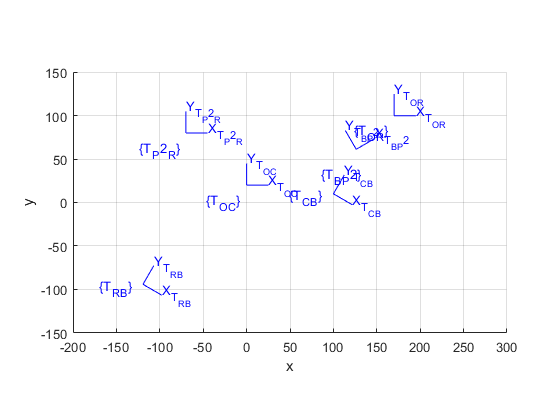

figure
plotvol([-200 300 -150 150 0 1])
view(2)
trplot2(T_C_B , 'frame', 'T_C_B' , 'color', 'b', 'length', 25);
hold on
trplot2(T_P2_R, 'frame', 'T_P2_R', 'color', 'b', 'length', 25);
trplot2(T_O_R , 'frame', 'T_O_R' , 'color', 'b', 'length', 25);
trplot2(T_O_C , 'frame', 'T_O_C' , 'color', 'b', 'length', 25);
trplot2(T_B_P2, 'frame', 'T_B_P2', 'color', 'b', 'length', 25);
trplot2(T_R_B , 'frame', 'T_R_B' , 'color', 'b', 'length', 25);
hold off

### Plot de puntos de ejemplo

Mostramos un ejemplo de como se verian todos los puntos tomando los puntos de ejemplo:

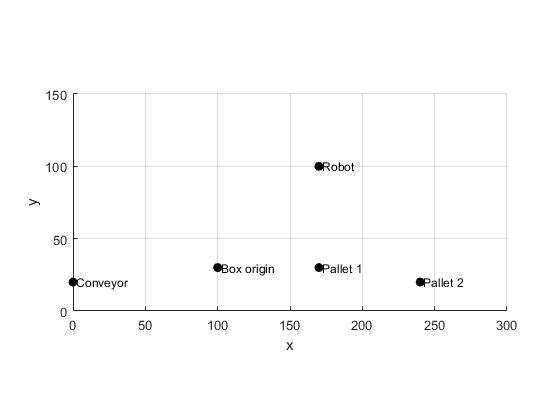

figure
plotvol([0 300 0 150 0 1])
view(2) % 2D
plot_point(robot   , 'label', 'Robot'     , 'solid', 'ko')
hold on
plot_point(conveyor, 'label', 'Conveyor'  , 'solid', 'ko'); 
plot_point(box     , 'label', 'Box origin', 'solid', 'ko'); 
plot_point(pallet1 , 'label', 'Pallet 1'  , 'solid', 'ko');
plot_point(pallet2 , 'label', 'Pallet 2'  , 'solid', 'ko');
view(2)
hold off

### Plot de puntos calculados a partir de las translaciones

Este es el resultado final, utilizando las translaciones en base al punto de origen (0,0). Se puede ver claramente la posición correcta de todos los elementos y su rotación.

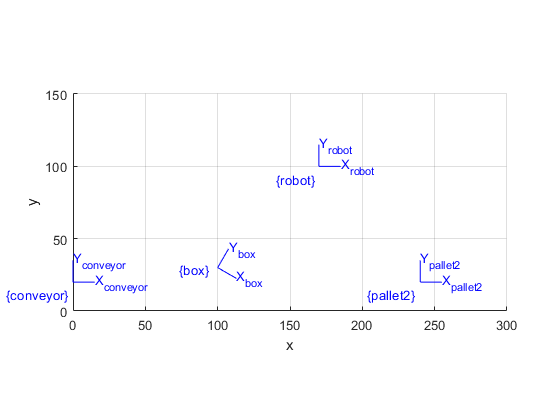

figure
plotvol([0 300 0 150 0 1])
view(2) % 2D
trplot2(T_O_R             , 'frame', 'robot'   , 'color', 'b', 'length', 15);
trplot2(T_O_C             , 'frame', 'conveyor', 'color', 'b', 'length', 15);
trplot2(T_O_C*T_C_B       , 'frame', 'box'     , 'color', 'b', 'length', 15);
trplot2(T_O_C*T_C_B*T_B_P2, 'frame', 'pallet2' , 'color', 'b', 'length', 15);
view(2)
hold off